clear
clc
% 常数
global Yb ab vb t A_exp a0_exp
Yb = 130.0232;
ab = 2.87477;
vb = 0.50525;
vs = 0.50525;
temp =     [0.0685    4.0259    2.8467  316.2175
    0.0588    4.0311    2.8504  308.5386
    0.0514    4.0351    2.8533  302.7956
    0.0457    4.0383    2.8555  298.3368
    0.0412    4.0409    2.8573  294.7741
    0.0374    4.0430    2.8588  291.8617
    0.0343    4.0448    2.8601  289.4361
    0.0317    4.0463    2.8612  287.3847
    0.0294    4.0476    2.8621  285.6270
    0.0275    4.0488    2.8629  284.1040
    0.0257    4.0498    2.8636  282.7718
    0.0242    4.0507    2.8643  281.5964
    0.0229    4.0515    2.8648  280.5519
    0.0217    4.0522    2.8653  279.6173
    0.0206    4.0529    2.8658  278.7764
    0.0196    4.0534    2.8662  278.0156
    0.0187    4.0540    2.8666  277.3240
    0.0179    4.0545    2.8669  276.6926
    0.0172    4.0549    2.8673  276.1138
    0.0165    4.0553    2.8676  275.5813
    0.0158    4.0557    2.8678  275.0899
    0.0153    4.0561    2.8681  274.6348
    0.0147    4.0564    2.8683  274.2123
    0.0142    4.0567    2.8685  273.8189
    0.0137    4.0570    2.8687  273.4518
    0.0133    4.0573    2.8689  273.1083
    0.0115    4.0584    2.8697  271.6774
    0.0100    4.0593    2.8703  270.5955
    0.0068    4.0613    2.8718  268.0416
    0.0051    4.0623    2.8725  266.7490
    0.0041    4.0630    2.8729  265.9683
    0.0034    4.0634    2.8733  265.4457
    1e-100    4.0655    2.8748  262.8064];

t = temp(:,1)

t =     0.0685
    0.0588
    0.0514
    0.0457
    0.0412
    0.0374
    0.0343
    0.0317
    0.0294
    0.0275


1./t

ans = 1.0e+100 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



% 定义实验数据
a0_exp = temp(:,3);   % 实验数据中的目标函数a0值
A_exp  = temp(:,4);    % 实验数据中的目标函数A值

% 定义参数值
x_fit_a0 = [144.11029, 2.83451, 4.87382, 0.50525]; % 初始参数值


% 计算拟合后的目标函数值

a0_fit_a0 = objectivea0(x_fit_a0)

Ys = 144.1103

as = 2.8345

ts = 4.8738

vs = 0.5053

  130.0232

    0.5052

    2.8748

    0.0685
    0.0588
    0.0514
    0.0457
    0.0412
    0.0374
    0.0343
    0.0317
    0.0294
    0.0275
    0.0257
    0.0242
    0.0229
    0.0217
    0.0206
    0.0196
    0.0187
    0.0179
    0.0172
    0.0165
    0.0158
    0.0153
    0.0147
    0.0142
    0.0137
    0.0133
    0.0115
    0.0100
    0.0068
    0.0051
    0.0041
    0.0034
    0.0000



temp1 = 1.0e+103 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


temp2 = 1.0e+102 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


a0 =     2.8467
    2.8504
    2.8533
    2.8555
    2.8573
    2.8589
    2.8601
    2.8612
    2.8621
    2.8629


a0_fit_a0 =     2.8467
    2.8504
    2.8533
    2.8555
    2.8573
    2.8589
    2.8601
    2.8612
    2.8621
    2.8629


## plot fit_a0

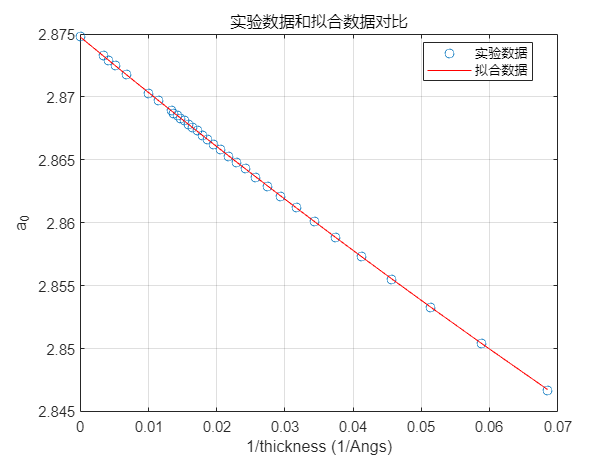

% 绘制实验数据
plot(t, a0_exp, 'o', 'DisplayName', '实验数据');
hold on

% 绘制拟合数据
plot(t, a0_fit_a0, 'r-', 'DisplayName', '拟合数据');

% 添加图例
legend('Location', 'best');

% 添加标签和标题
xlabel('1/thickness (1/Angs)');
ylabel('a_0');
title('实验数据和拟合数据对比');

% 显示网格
grid on

% 保持坐标轴比例一致
%axis equal
xlim('auto')
% 显示图形
hold off

% 定义目标函数A

function A = objectiveA(x)
    global Yb ab vb t
    Ys = x(1);
    as = x(2);
    ts = x(3);
    vs = x(3);
    % 根据参数a、b、c计算目标函数A的值
    A = -((as.*(2.*ts-1./t).*(vs-1).*Yb-2.*ab.*ts.*(vb-1).*Ys).^2)./(1./t.*(vb-1).*(vs-1).*(-as.^2.*(2.*ts-1./t).*(vs-1).*Yb+2.*ab.^2.*ts.*(vb-1).*Ys)); % 计算目标函数A的具体表达式
end

% 定义目标函数a0
function a0 = objectivea0(x)
    global Yb ab vb t
    Ys = x(1)
    as = x(2)
    ts = x(3)
    vs = x(4)
    disp(Yb)
    disp(vb)
    disp(ab)
    disp(t)
    % 根据参数a、b、c计算目标函数A的值
    temp1=(ab*as*(-as*(2*ts-1./t)*(vs-1)*Yb+2*ab*ts*(vb-1)*Ys))
    temp2=(-as^2*(2*ts-1./t)*(vs-1)*Yb+2*ab^2*ts*(vb-1)*Ys)
    a0=temp1./temp2
end
